Seguidor de referência constante

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

Matrizes

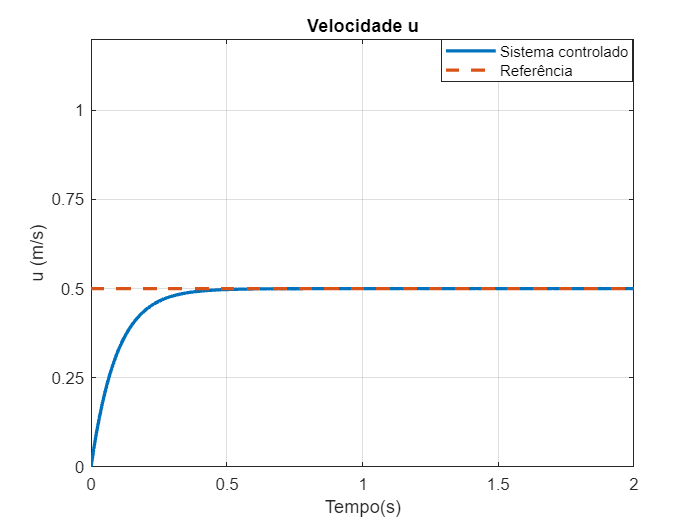

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v); 
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];


B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];

D = zeros(1,3);

E = [1/m_u;1/m_v;0]; %entrada de disturbio

B_novo = [B E];

D_novo = [D zeros(size(C,1),size(E,2))];


A2 = pinv([A B; C D]);  

N0 = [zeros(3,3); [1,0,0]];
Nxu = A2*N0;
Nx = Nxu(1:3,:);
Nu = Nxu(4:6,:);


Q = diag([50000,45000,40000]); %matriz de ponderação Q

R_ = diag([0.002,0.0004,0.005]); %Matriz de ponderação P

%Calcule a matriz de ganho de realimentação K usando o projeto do controlador LQR

K = lqr(A, B, Q, R_);

F = A -B*K;

t = 0:0.01:8;  % tempo

x_r = [0.5;0;0];

urp = (Nu + K*Nx)*x_r;

B2 = B*urp;

sys = ss(F, B2, C, 0);

y = step(sys,t);

sx = ones(length(t), 1)*x_r(1);

figure(1)
plot(t, y(:,1), '-', 'LineWidth', 2)
title('Velocidade u')
ylabel('u (m/s)')
xlabel('Tempo(s)')
grid on
hold on
p_10 = plot(t, sx, '--', 'LineWidth', 2);
hold off
legend('Sistema controlado', 'Referência')
ylim([0 1.2]);
ax = gca; 
ax.YTick = 0:0.25:1.5;
xlim([0 2])

legend("Position", [0.62845,0.84294,0.27679,0.082143])